# Barrel distortion removal

The barrel distortion is removed in two ways:

- A common polynominal approach. ([Shah et. al. 1994](http://ieeexplore.ieee.org/xpls/abs_all.jsp?arnumber=351044)) 

- A hardware implementation friendly [coefficient method](http://ieeexplore.ieee.org/xpls/abs_all.jsp?arnumber=6011854&tag=1). ([Blasinski et al. ICME 2011](http://ieeexplore.ieee.org/xpls/abs_all.jsp?arnumber=6011854&tag=1))

Henryk Blasinski and BW 2012

ieInit

## Create a scene of grid line

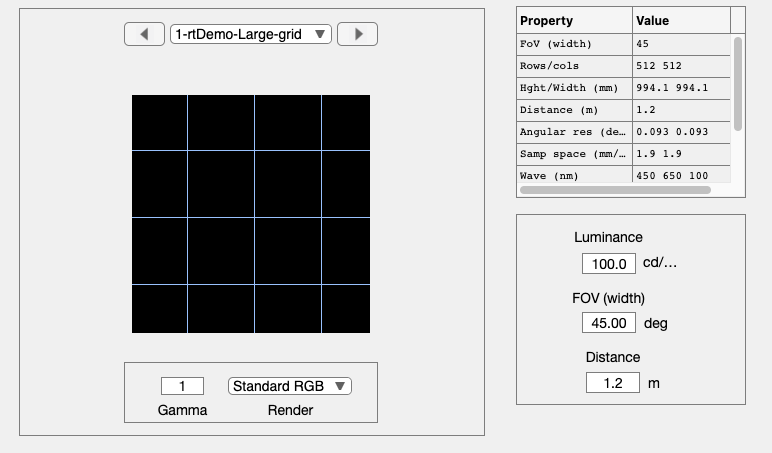

scene = sceneCreate('gridlines',[512 512], 48);
scene = sceneInterpolateW(scene,(450:100:650));  % Small wavelength sample
scene = sceneSet(scene,'hfov',45);
scene = sceneSet(scene,'name','rtDemo-Large-grid');

% Show the grid line scene
ieAddObject(scene); sceneWindow;

## Compute irradiance through a wide angle lens

% Set up default optical image
oi = oiCreate();

% Load in the wide angle lens optics file created by Zemax (zm)
opticsFileName = fullfile(isetRootPath,'data','optics','zmWideAngle.mat');
load(opticsFileName,'optics');

% Set the oi with the optics loaded from the file
oi = oiSet(oi,'optics',optics);

% Retrieve it and print its name to verify and inform user
optics = oiGet(oi,'optics');
fprintf('Ray trace optics: %s\n',opticsGet(optics,'lensFile'));

Ray trace optics: wideAngle.zmx


% Now, match the scene properties
oi = oiSet(oi,'wangular',sceneGet(scene,'wangular'));
oi = oiSet(oi,'wave',sceneGet(scene,'wave'));

% Match the scene distance and the rt distance.  They are both essentially
% infinite.
scene   = sceneSet(scene,'distance',2);  % Two meters - essentially inf
optics  = opticsSet(optics,'rtObjectDistance',sceneGet(scene,'distance','mm'));

oi = oiSet(oi,'optics',optics);
oi = oiSet(oi,'optics model','ray trace');

% ieSessionSet('waitbar','on')
oi = oiCompute(oi,scene);

Geometric distortion ...

Pre-computing PSFs...Setting up for scene rtDemo-Large-grid
Eccentricity bands: 0.000 (um)
Eccentricity bands: 87.491 (um)
Eccentricity bands: 174.981 (um)
Eccentricity bands: 262.472 (um)
Eccentricity bands: 349.962 (um)
Eccentricity bands: 437.453 (um)
PSF sample grid: 54 by 54
Done precomputing PSFs.
Applying PSFs.
6 eccentricity bands
Done applying PSFs.


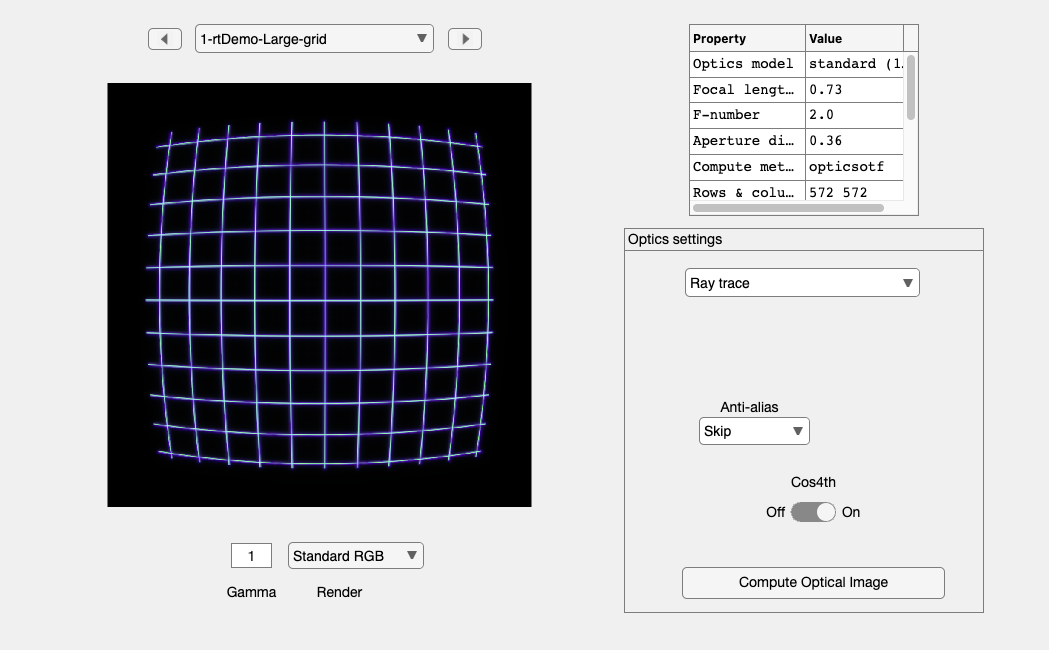

oiWindow(oi);

## Correct the distorted image

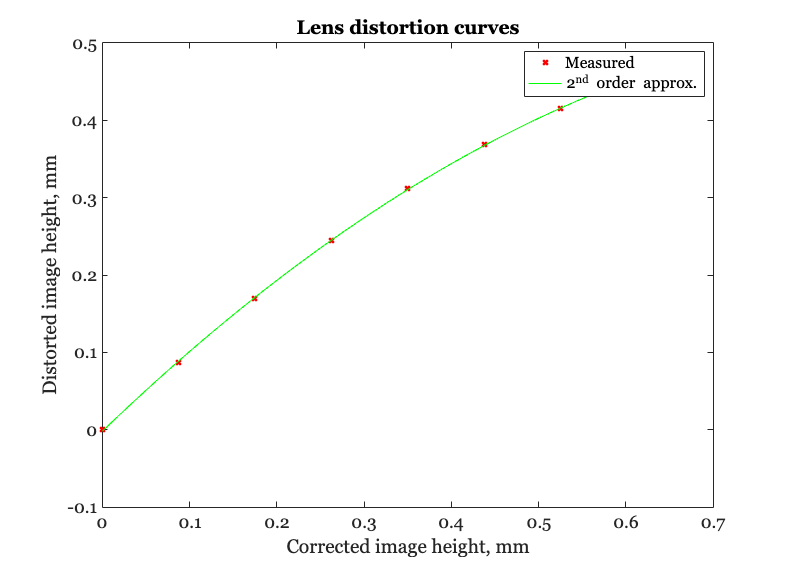

Corrected = opticsGet(optics,'rtgeomfieldheight','mm');
CorrectedMax = opticsGet(optics,'rtgeommaxfieldheight','mm');

% The distortion function depends on the wavelength, here we are somewhat
% randomly selecting the middle wavelengths distortion curve.
DistWavelengths = opticsGet(optics,'rtgeomwavelength');
Distorted = opticsGet(optics,'rtgeomfunction',DistWavelengths(2),'mm');

% Compute a 2nd order polynominal approximation
polycoefs = polyfit(Corrected,Distorted,2);

% Plot the approximation for 100 equally spaced sample points
CorrImHeight = linspace(0,CorrectedMax,100);
DistImHeight = polyval(polycoefs,CorrImHeight);

ieNewGraphWin;
plot(Corrected,Distorted,'x','LineWidth',2); hold on;
plot(CorrImHeight,DistImHeight,'g');
xlabel('Corrected image height, mm');
ylabel('Distorted image height, mm');
title('Lens distortion curves');
legend('Measured','2^{nd} order approx.');

## Remove the barrel distortion from the optical image

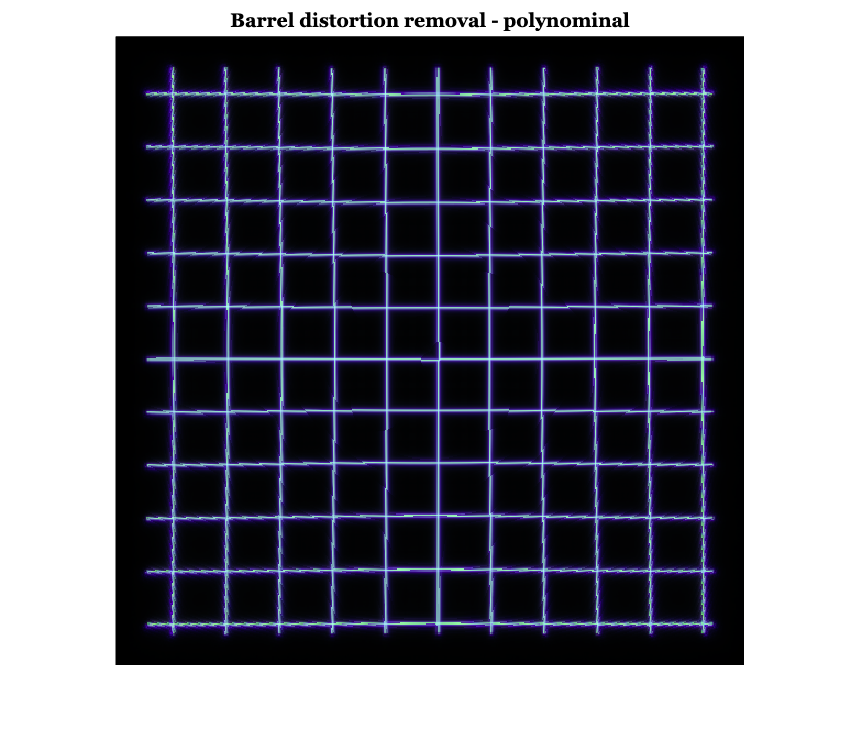

imgRows = oiGet(oi,'rows');
imgCols = oiGet(oi,'cols');

% Compute the width and height of a pixel in mm.
imgDistance = oiGet(oi,'distance per sample','mm');
pxH = imgDistance(1);
pxW = imgDistance(2);

Center = oiGet(oi,'centerpixel');
yc = Center(1);
xc = Center(2);

DistortedImage = oiGet(oi,'rgb image',0.6);
CorrectedImage = zeros(imgRows,imgCols,3);

h = waitbar(0,'Correcting distortion');
for y=1:imgRows
    waitbar(y/imgRows,h);
    for x=1:imgCols
        % Compute pixel coordinates in mm:
        xx = (x-xc)*pxW;
        yy = (y-yc)*pxH;
        
        % Compute the azimuth angle, consider a separate case when theta=90
        % degrees
        if xx~=0
            theta = atand(abs(yy/xx));
        else
            theta = 90;
        end
        
        % Compute the height of the pixel
        r_corr = sqrt(xx^2 + yy^2);
        % Compute the corresponding height in the distorted domain
        r_dist = polyval(polycoefs,r_corr);
        
        % Convert back to rectangular coordinates, make sure the
        % coordinates have consistend signs.
        x_dist = (sign(xx)*round(r_dist*cosd(theta)/pxW) + xc);
        y_dist = (sign(yy)*round(r_dist*sind(theta)/pxH) + yc);
        
        % Copy image intensity:
        CorrectedImage(y,x,:) = DistortedImage(y_dist,x_dist,:);
        
    end
end
close(h)

ieNewGraphWin; imshow(CorrectedImage);
title('Barrel distortion removal - polynominal');

## Remove barel distortion using the coefficient method

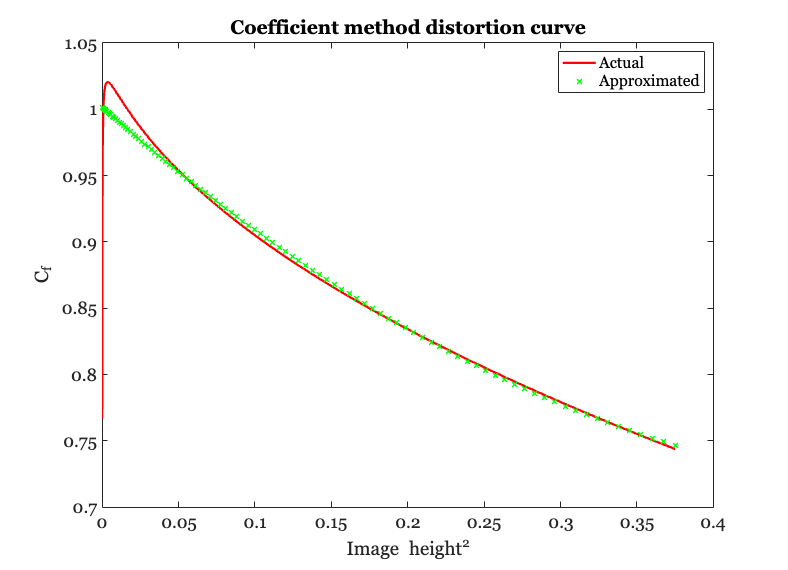

% First we need to compute the distortion function the classical way
Corrected = opticsGet(optics,'rtgeomfieldheight','mm');
CorrectedMax = opticsGet(optics,'rtgeommaxfieldheight','mm');
CorrImHeight = linspace(0,CorrectedMax,100);

DistWavelengths = opticsGet(optics,'rtgeomwavelength');
Distorted = opticsGet(optics,'rtgeomfunction',DistWavelengths(2),'mm');
polycoefs = polyfit(Corrected,Distorted,2);

% Now we define the Cf as a ratio between the distorted and corrected image
% heights
Cf = polyval(polycoefs,CorrImHeight,2)./CorrImHeight;

% Since the first element of CorrImHeight is zero we get a NaN:
Cf = Cf(2:end);
CorrImHeight = CorrImHeight(2:end);
% And we fit in a polynominal s.t. Cf=function(height^2)
pc = polyfit(CorrImHeight.^2,Cf,2);
CfApprox = polyval(pc,CorrImHeight.^2);

% Plot the distortion curves
ieNewGraphWin;
plot(CorrImHeight.^2,Cf,'r','LineWidth',2); hold on;
plot(CorrImHeight.^2,CfApprox,'gx');
xlabel('{Image height}^2');
ylabel('C_f');
title('Coefficient method distortion curve');
legend('Actual','Approximated');

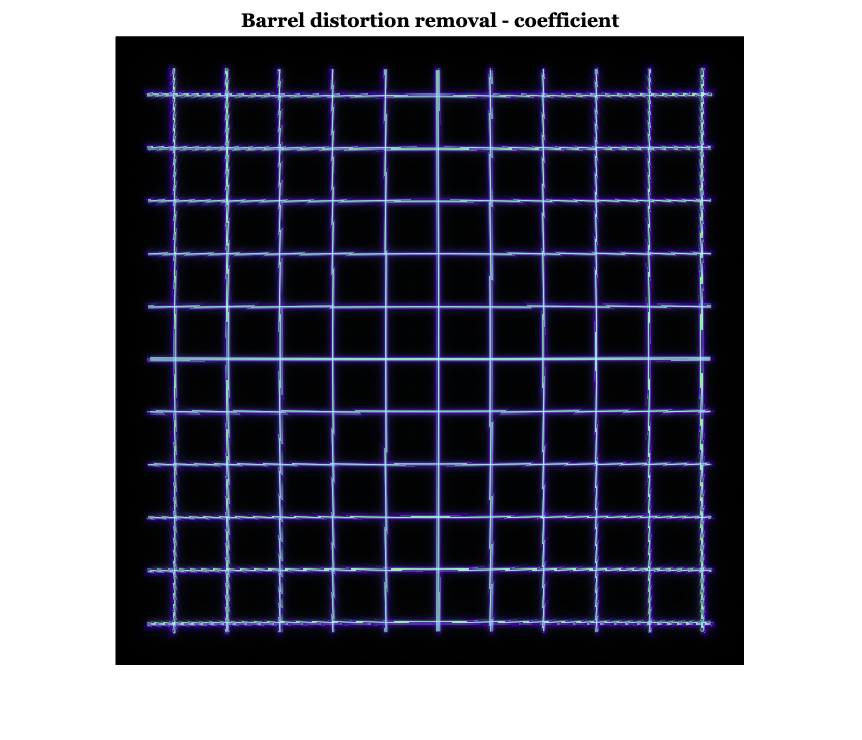

% As previously we extract optical image parameters.
imgRows = oiGet(oi,'rows');
imgCols = oiGet(oi,'cols');

% Compute the width and height of a pixel in mm.
imgDistance = oiGet(oi,'distance per sample','mm');
pxH = imgDistance(1);
pxW = imgDistance(2);

Center = oiGet(oi,'centerpixel');
yc = Center(1);
xc = Center(2);

% Remove the distortion
DistortedImage = oiGet(oi,'rgb image',0.6);
CorrectedImage = zeros(imgRows,imgCols,3);

h = waitbar(0,'Correcting distortion');
for y=1:imgRows
    waitbar(y/imgRows,h);
    for x=1:imgCols
        % Compute pixel coordinates in mm:
        xx = (x-xc)*pxW;
        yy = (y-yc)*pxH;
        
        % Compute the pixel height
        r_corr = xx^2 + yy^2;
        
        % Compyte the coordinate correction coefficient
        C_f = polyval(pc,r_corr);
        
        % Apply the correction coefficient to corrected coordinates:
        y_dist = round(yy/pxH*C_f + yc);
        x_dist = round(xx/pxW*C_f + xc);
        
        % Copy image intensity:
        CorrectedImage(y,x,:) = DistortedImage(y_dist,x_dist,:);
        
    end
end
close(h)

ieNewGraphWin; imshow(CorrectedImage);
title('Barrel distortion removal - coefficient');